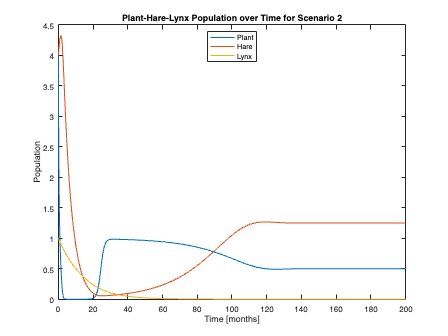

% Scenario 2 Description: The lynx population goes extinct (population very close to zero) after a year, plants and 
% hares stabilize within 120 months.


t0 = 0;             
tfinal = 200;       
y0= [4 4 1];        
tspan = [t0 tfinal];
a1 = 1;             
a2 = 0.2;           
b1 = 3;             
b2 = 9;             
d1 = 0.2;           
d2 = 0.09;          

% Each point on the population vs. time graph is calculated using the
% provided function called "plants_hare_lynx_" which can be found in the
% GitHub repository. Here, the described parameters are inputted into the
% function and the resulting points are given. 
[t,y] = ode23(@(t,y) plants_hare_lynx_(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);


% Plotting the population over time for Scenario 3
figure("Name",'hare-lynx for S2');
plot(t,y)
title('Plant-Hare-Lynx Population over Time for Scenario 2');
xlabel('Time [months]');
ylabel('Population');
legend('Plant','Hare','Lynx','Location','North');

Based on the resulting plot, we can see that the population of lynxes becomes extinc (reaches zero) around the 60 month mark. The hares and the plants begin to stabalise their population around the 120 month mark. This was done by figuring out how to make the lynxes go extinct, without simply killing all the hares (we had to make sure that some hares were still alive in order to stabalise the hare-plant relationship). After inspecting various variables and making educated judgements about which variables to change and when, the requested  scenerio was obtained. 

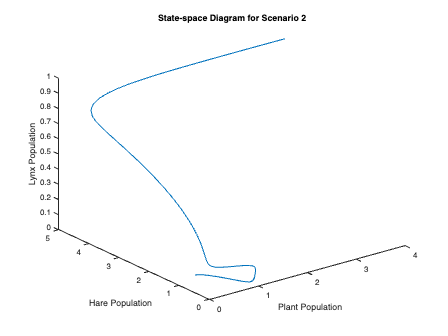

% Plotting the state-space diagram for Scenario 2
figure("Name",'State space for S2')
plot3(y(:,1),y(:,2),y(:,3))
title('State-space Diagram for Scenario 2')
xlabel('Plant Population')
ylabel('Hare Population')
zlabel('Lynx Population')